Configuración

filename = 'identificacion_motor.csv';  % ajusta nombre
Ts = 0.01;     % tiempo de muestreo nominal en s (ej. 0.01=10ms)
save_plots_folder = 'resultados';

if ~exist(save_plots_folder,'dir'), mkdir(save_plots_folder); end

Caraga de archivos

T = readtable(filename);
t_cmd = T.t_cmd - T.t_cmd(1);
t_odom = T.t_odom - T.t_odom(1);
u = T.u_left;      % entrada (usa u_left si necesitas otro)
y = T.w_left;      % salida

Procesamiento de datos

%% --- CLEAN: eliminar NaN/Inf y duplicados ---
valid = isfinite(t_cmd) & isfinite(t_odom) & isfinite(u) & isfinite(y);
t_cmd = t_cmd(valid); t_odom = t_odom(valid); u = u(valid); y = y(valid);

[t_cmd, ia] = unique(t_cmd, 'stable'); u = u(ia);
[t_odom, ib] = unique(t_odom, 'stable'); y = y(ib);

%% --- SYNCHRONIZE: construir malla uniforme o usar t_cmd ---
% Opción 1: usar t_common = t_cmd (si t_cmd uniforme o cercano)
t_common = t_cmd;
y_sync = interp1(t_odom, y, t_common, 'linear', 'extrap');

% Si prefieres malla uniforme:
% t_common = t_cmd(1):Ts:t_cmd(end);
% u_common = interp1(t_cmd, u, t_common, 'previous','extrap'); % hold input
% y_sync = interp1(t_odom, y, t_common, 'linear','extrap');

DATOS

%% --- ANÁLISIS DEL RANGO DE OPERACIÓN ---
fprintf('\n=== ANÁLISIS DE RANGO ===\n');


=== ANÁLISIS DE RANGO ===



% Verificar rango de datos de entrenamiento
fprintf('Datos de entrenamiento:\n');

Datos de entrenamiento:


fprintf('  Entrada u: [%.2f, %.2f]\n', min(u), max(u));

  Entrada u: [-63.00, 63.00]


fprintf('  Salida y: [%.2f, %.2f] rad/s\n', min(y), max(y));

  Salida y: [-11.92, 11.98] rad/s



% Verificar si el modelo es válido para todo el rango
if abs(min(u)) < 63 || abs(max(u)) < 63
    fprintf('⚠ Los datos no cubren todo el rango de entrada [-63, 63]\n');
    fprintf('   El modelo puede no ser preciso en extremos.\n');
end

% Verificar linealidad
fprintf('\nVerificación de linealidad:\n');


Verificación de linealidad:


% Podrías hacer regresión para ver si hay saturación en datos
u_abs = abs(u);
idx_high = u_abs > 50; % Cerca de la saturación
idx_mid = (u_abs > 20) & (u_abs <= 50);
idx_low = u_abs <= 20;

if ~isempty(idx_high)
    fprintf('  %.1f%% de datos cerca de saturación (>50)\n', 100*sum(idx_high)/length(u));
end

  18.2% de datos cerca de saturación (>50)


if ~isempty(idx_mid)
    fprintf('  %.1f%% de datos en rango medio (20-50)\n', 100*sum(idx_mid)/length(u));
end

  36.5% de datos en rango medio (20-50)


if ~isempty(idx_low)
    fprintf('  %.1f%% de datos en rango bajo (<=20)\n', 100*sum(idx_low)/length(u));
end

  45.3% de datos en rango bajo (<=20)


Figuras

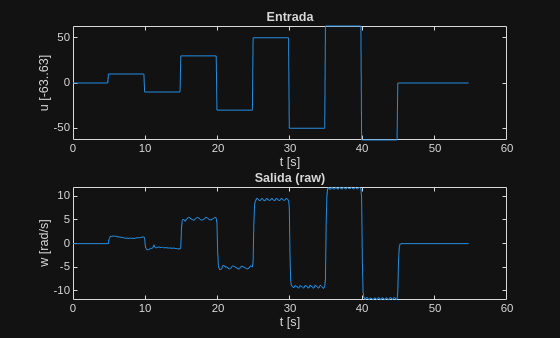

%% --- PLOT raw signals ---
figure; subplot(2,1,1); plot(t_cmd, u); xlabel('t [s]'); ylabel('u [-63..63]'); title('Entrada');
subplot(2,1,2); plot(t_odom, y); xlabel('t [s]'); ylabel('w [rad/s]'); title('Salida (raw)');
saveas(gcf, fullfile(save_plots_folder,'raw_signals.png'));

Modelamiento de la planta

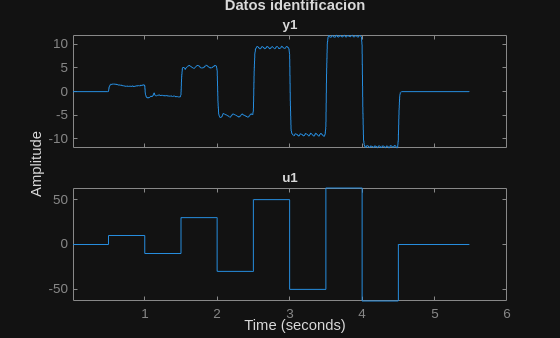

%% --- iddata ---
data_id = iddata(y_sync(:), u(:), Ts);  % y,u should be column vectors

figure; plot(data_id); title('Datos identificacion');
saveas(gcf, fullfile(save_plots_folder,'data_id.png'));


%% --- Estimate delay (optional) ---
% Estimar retardo con correlación cruzada
[XC, lags] = xcorr(y_sync - mean(y_sync), u - mean(u), 200, 'coeff');
[~, iMax] = max(XC);
lag_samples = lags(iMax);
delay_est = lag_samples * Ts;
fprintf('Delay estimate = %.4f s (lag = %d samples)\n', delay_est, lag_samples);

Delay estimate = 0.0100 s (lag = 1 samples)



%% --- Model estimation: probar varios metodos/ordenes ---
% ARX (orden 2)
na = 2; nb = 2; nk = max(0, round(delay_est/Ts)); % nk = delay en muestras
model_arx = arx(data_id, [na nb nk]);

% OE / TFEST (prueba 1er u 2do orden)
sys_tf1 = tfest(data_id, 1, 0, nk, 'Ts', Ts);
sys_tf2 = tfest(data_id, 2, 0, nk, 'Ts', Ts);


Comparativa de modelos

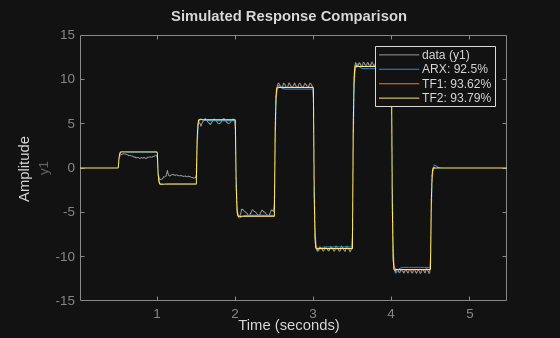

% Comparar ajustes
figure; compare(data_id, model_arx, sys_tf1, sys_tf2);
legend('data','ARX','TF1','TF2');
saveas(gcf, fullfile(save_plots_folder,'compare_models.png'));


% --- CÁLCULO SIMPLE Y ROBUSTO DE FIT ---
% Para ARX
[y_arx_sim] = compare(data_id, model_arx);
% Extraer datos numéricos de forma segura
if isa(y_arx_sim, 'iddata')
    try
        y_arx_data = y_arx_sim.OutputData;
    catch
        y_arx_data = y_arx_sim.y;
    end
else
    y_arx_data = y_arx_sim;
end

y_sync_vec = y_sync(:);
y_arx_vec = y_arx_data(:);

fit_arx = 100 * (1 - norm(y_sync_vec - y_arx_vec) / norm(y_sync_vec - mean(y_sync_vec)));
fprintf('Fit ARX: %.2f %%\n', fit_arx);

Fit ARX: 92.50 %



% Para TF2
[y_tf2_sim] = compare(data_id, sys_tf2);
if isa(y_tf2_sim, 'iddata')
    try
        y_tf2_data = y_tf2_sim.OutputData;
    catch
        y_tf2_data = y_tf2_sim.y;
    end
else
    y_tf2_data = y_tf2_sim;
end

y_tf2_vec = y_tf2_data(:);
fit_tf2 = 100 * (1 - norm(y_sync_vec - y_tf2_vec) / norm(y_sync_vec - mean(y_sync_vec)));
fprintf('Fit TF2: %.2f %%\n', fit_tf2);

Fit TF2: 93.79 %


SELECCION DEL MODELO

%% --- Select model (ejemplo sys_tf2) ---
sysz = sys_tf2;  % si tfest devuelve discreto con Ts, está listo; si continuo -> c2d
if sysz.Ts == 0
    sysz = c2d(sysz, Ts, 'zoh');
end

% Parametros del modelo (numerador/denominador)
[numz, denz] = tfdata(sysz, 'v');
fprintf('\n=== FUNCIÓN DE TRANSFERENCIA DISCRETA ===\n');


=== FUNCIÓN DE TRANSFERENCIA DISCRETA ===


fprintf('G(z) = (');

G(z) = (

for i = 1:length(numz)
    if i > 1, fprintf(' + '); end
    fprintf('%.6g z^{%d}', numz(i), length(numz)-i);
end

0.11885 z^{2}

 + 

0 z^{1}

 + 

0 z^{0}

fprintf(') / (');

) / (

for i = 1:length(denz)
    if i > 1, fprintf(' + '); end
    fprintf('%.6g z^{%d}', denz(i), length(denz)-i);
end

1 z^{2}

 + 

-0.423287 z^{1}

 + 

0.0776973 z^{0}

fprintf(')\n');

)


GANANCIAS PID

%% --- REDISEÑO PID CONSIDERANDO SATURACIÓN ---
fprintf('\n=== REDISEÑO PID CON LÍMITES ±63 ===\n');


=== REDISEÑO PID CON LÍMITES ±63 ===



% Definir límites de saturación (deberían ser constantes conocidas)
u_min = -63;
u_max = 63;

% Calcular ganancia máxima teórica basada en límites
% Supongamos referencia máxima de 30 rad/s (ajusta según tu aplicación)
ref_max = 30; % rad/s

% Ganancia máxima para no saturar inmediatamente
Kp_max_theoretical = u_max / ref_max;
fprintf('Ganancia máxima teórica (sin I,D): Kp_max = %.4f\n', Kp_max_theoretical);

Ganancia máxima teórica (sin I,D): Kp_max = 2.1000



% Diseñar PID con límites en mente
% Usar pidtune con especificaciones más realistas
opts = pidtuneOptions('DesignFocus', 'balanced'); % balanced, reference-tracking, disturbance-rejection
C_sat = pidtune(sysz, 'PIDF', opts);

% Verificar si la ganancia es razonable
if C_sat.Kp > Kp_max_theoretical
    fprintf('⚠ Advertencia: Kp=%.4f puede causar saturación rápida\n', C_sat.Kp);
    fprintf('   Considerar reducir ganancia a ~%.4f\n', Kp_max_theoretical * 0.8);
    
    % Opcional: ajustar manualmente la ganancia
    C_sat.Kp = min(C_sat.Kp, Kp_max_theoretical * 0.8);
    fprintf('   Ajustado a: Kp = %.6f\n', C_sat.Kp);
end

% Mostrar nuevo controlador
fprintf('\nPID considerando saturación:\n');


PID considerando saturación:


fprintf('  Kp = %.6f\n', C_sat.Kp);

  Kp = 0.027532


fprintf('  Ki = %.6f\n', C_sat.Ki);

  Ki = 5.506323


fprintf('  Kd = %.6f\n', C_sat.Kd);

  Kd = 0.000000


if isprop(C_sat, 'Tf')
    fprintf('  Tf = %.6f\n', C_sat.Tf);
end

  Tf = 0.000000



% Calcular parámetros clásicos
Kc = C_sat.Kp;
if C_sat.Ki ~= 0
    Ti = C_sat.Kp / C_sat.Ki;
else
    Ti = Inf;
end
if C_sat.Kp ~= 0 && C_sat.Kd ~= 0
    Td = C_sat.Kd / C_sat.Kp;
else
    Td = 0;
end

fprintf('\nFORMA CLÁSICA (Kc, Ti, Td):\n');


FORMA CLÁSICA (Kc, Ti, Td):


fprintf('  Kc = %.6f\n', Kc);

  Kc = 0.027532


if isfinite(Ti)
    fprintf('  Ti = %.6f s\n', Ti);
else
    fprintf('  Ti = Inf\n');
end

  Ti = 0.005000 s


fprintf('  Td = %.6f s\n', Td);

  Td = 0.000000 s



% Para implementación
fprintf('\nPARA IMPLEMENTACIÓN (Ts = %.4f s):\n', Ts);


PARA IMPLEMENTACIÓN (Ts = 0.0100 s):


if C_sat.Kd == 0
    % Solo PI
    fprintf('Forma PI discreto:\n');
    fprintf('  u[k] = u[k-1] + Kp*(e[k]-e[k-1]) + Ki*Ts*e[k]\n');
    fprintf('  u[k] = u[k-1] + %.6f*(e[k]-e[k-1]) + %.6f*e[k]\n', C_sat.Kp, C_sat.Ki*Ts);
else
    % PID completo
    fprintf('Forma PID discreto:\n');
    fprintf('  u[k] = u[k-1] + Kp*(e[k]-e[k-1]) + Ki*Ts*e[k] + (Kd/Ts)*(e[k]-2e[k-1]+e[k-2])\n');
    fprintf('  u[k] = u[k-1] + %.6f*(e[k]-e[k-1]) + %.6f*e[k] + %.6f*(e[k]-2e[k-1]+e[k-2])\n', C_sat.Kp, C_sat.Ki*Ts, C_sat.Kd/Ts);
end

Forma PI discreto:


  u[k] = u[k-1] + Kp*(e[k]-e[k-1]) + Ki*Ts*e[k]


  u[k] = u[k-1] + 0.027532*(e[k]-e[k-1]) + 0.055063*e[k]



dc = dcgain(sysz);
fprintf('Ganancia DC del modelo: %.4f\n', dc);

Ganancia DC del modelo: 0.1816


fprintf('Señal de control requerida para ref=10 => u_req = %.2f\n', 10/dc);

Señal de control requerida para ref=10 => u_req = 55.06


VISUALIZACION DEL PID

% --- Construir controlador discreto (pid object) con Ts CORRECTO
Ts = sysz.Ts;

Cd = pid(C_sat.Kp, C_sat.Ki, C_sat.Kd, 'Ts', sysz.Ts);


% Verificación explícita
assert(Cd.Ts == sysz.Ts, 'ERROR: Ts del PID y la planta no coinciden');

% Construir lazo cerrado
L  = series(Cd, sysz);
CL = feedback(L, 1);


info = stepinfo(CL, 'SettlingTimeThreshold', 0.02); % 2%
disp(info);

         RiseTime: 2.1600
    TransientTime: 3.8700
     SettlingTime: 3.8700
      SettlingMin: 0.9001
      SettlingMax: 0.9996
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9996
         PeakTime: 7.7900



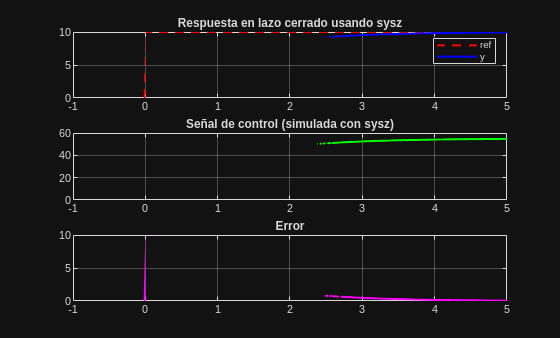




% Simular respuesta a referencia constante de 10 rad/s
t_sim = (-Ts:Ts:5)';             % empieza antes
ref   = 10 * ones(size(t_sim));
ref(1) = 0;                      % referencia inicial cero
[y_cl, t_out] = lsim(CL, ref, t_sim);

e = ref - y_cl;
[u_cl, ~] = lsim(Cd, e, t_sim);


% También obtener la señal de control (u = Cd * (ref - y))
%e = ref - y_cl;
%[u_cl, ~] = lsim(Cd, e, t_sim);

% Plot
figure;
subplot(3,1,1); plot(t_out, ref, 'r--', t_out, y_cl, 'b-','LineWidth',1.5); grid on;
title('Respuesta en lazo cerrado usando sysz'); legend('ref','y');
subplot(3,1,2); plot(t_out, u_cl, 'g-','LineWidth',1.5); grid on; title('Señal de control (simulada con sysz)');
subplot(3,1,3); plot(t_out, e, 'm-','LineWidth',1.5); grid on; title('Error');

Daiagrama de bode

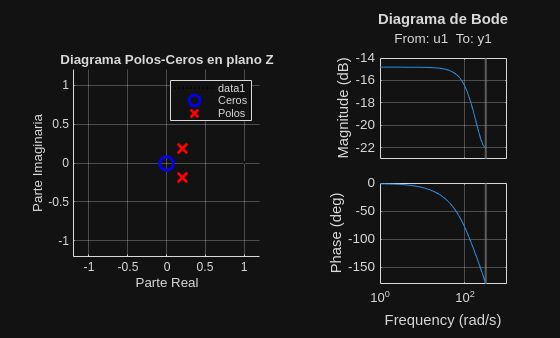

%% --- Poles, zeros, bode ---
figure;
% Polos y ceros manual
subplot(1,2,1);
zeros_sys = roots(numz);
poles_sys = roots(denz);

hold on;
% Círculo unidad
theta = linspace(0, 2*pi, 100);
plot(cos(theta), sin(theta), 'k:', 'LineWidth', 1);
% Polos y ceros
plot(real(zeros_sys), imag(zeros_sys), 'bo', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Ceros');
plot(real(poles_sys), imag(poles_sys), 'rx', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Polos');

grid on; axis equal; axis([-1.2 1.2 -1.2 1.2]);
xlabel('Parte Real'); ylabel('Parte Imaginaria');
title('Diagrama Polos-Ceros en plano Z');
legend show;

% Bode
subplot(1,2,2);
bode(sysz);
grid on;
title('Diagrama de Bode');

saveas(gcf, fullfile(save_plots_folder,'pz_bode.png'));


% Información en consola
fprintf('\n=== POLOS Y CEROS ===\n');


=== POLOS Y CEROS ===


for i = 1:length(poles_sys)
    fprintf('Polo %d: %.4f %+.4fj (|z| = %.4f)\n', i, real(poles_sys(i)), imag(poles_sys(i)), abs(poles_sys(i)));
end

Polo 1: 0.2116 +0.1814j (|z| = 0.2787)
Polo 2: 0.2116 -0.1814j (|z| = 0.2787)


fprintf('\n');
for i = 1:length(zeros_sys)
    fprintf('Cero %d: %.4f %+.4fj\n', i, real(zeros_sys(i)), imag(zeros_sys(i)));
end

Cero 1: 0.0000 +0.0000j
Cero 2: 0.0000 +0.0000j



% Verificación de estabilidad
if all(abs(poles_sys) < 1)
    fprintf('\n✓ Sistema DISCRETO ESTABLE\n');
else
    fprintf('\n⚠ Sistema DISCRETO INESTABLE\n');
    fprintf('   Polos fuera del círculo unidad:\n');
    for i = 1:length(poles_sys)
        if abs(poles_sys(i)) >= 1
            fprintf('   - Polo %d: |z| = %.4f\n', i, abs(poles_sys(i)));
        end
    end
end


✓ Sistema DISCRETO ESTABLE


Ajuste fino

figure('Name','Ajuste fino PID discreto','NumberTitle','off');

% ===== Sliders =====
sKp = uicontrol('Style','slider','Min',0.005,'Max',0.1,...
    'Value',Cd.Kp,'Units','normalized','Position',[0.08 0.02 0.22 0.05]);

sKi = uicontrol('Style','slider','Min',0,'Max',10,...
    'Value',Cd.Ki,'Units','normalized','Position',[0.36 0.02 0.22 0.05]);

sKd = uicontrol('Style','slider','Min',0,'Max',0.01,...
    'Value',0,'Units','normalized','Position',[0.64 0.02 0.22 0.05]);

% Etiquetas
uicontrol('Style','text','Units','normalized',...
    'Position',[0.08 0.07 0.22 0.03],'String','Kp');

uicontrol('Style','text','Units','normalized',...
    'Position',[0.36 0.07 0.22 0.03],'String','Ki');

uicontrol('Style','text','Units','normalized',...
    'Position',[0.64 0.07 0.22 0.03],'String','Kd');

% ===== Eje =====
ax = axes('Position',[0.1 0.18 0.8 0.72]);

while ishandle(sKp)
    Kp = sKp.Value;
    Ki = sKi.Value;
    Kd = sKd.Value;

    % PID discreto con filtro derivativo
    Ctmp = pid(Kp, Ki, 0, 'Ts', sysz.Ts);





    CLtmp = feedback(series(Ctmp, sysz), 1);

    % Plot
    cla(ax);
    step(CLtmp, 5);
    grid on;

    % Info dinámica
    info = stepinfo(CLtmp, 'SettlingTimeThreshold', 0.02);
    poles = pole(CLtmp);

    title(sprintf([ ...
    'Kp=%.4f   Ki=%.2f   Kd=%.4f\n' ...
    'Ts=%.2fs | Ts(2%%)=%.2fs | OS=%.1f%% | Tr=%.2fs\n' ...
    'Polos dominantes: %.4f   %.4f'], ...
    Kp, Ki, Kd, ...
    Ts, info.SettlingTime, info.Overshoot, info.RiseTime, ...
    poles(1), poles(2)));

    drawnow;
end



% Mostrar nuevo controlador
fprintf('\nPID considerando saturación:\n');


PID considerando saturación:


fprintf('  Kp = %.6f\n', Kp);

  Kp = 0.027532


fprintf('  Ki = %.6f\n', Ki);

  Ki = 5.506323


fprintf('  Kd = %.6f\n', Kd);

  Kd = 0.000000




% Calcular parámetros clásicos
Kc = Kp;
if Ki ~= 0
    Ti = Kp / Ki;
else
    Ti = Inf;
end
if Kp ~= 0 && Kd ~= 0
    Td = Kd / Kp;
else
    Td = 0;
end

fprintf('\nFORMA CLÁSICA (Kc, Ti, Td):\n');


FORMA CLÁSICA (Kc, Ti, Td):


fprintf('  Kc = %.6f\n', Kc);

  Kc = 0.027532


if isfinite(Ti)
    fprintf('  Ti = %.6f s\n', Ti);
else
    fprintf('  Ti = Inf\n');
end

  Ti = 0.005000 s


fprintf('  Td = %.6f s\n', Td);

  Td = 0.000000 s



fprintf(' Kp=%.4f   Ki=%.2f   Kd=%.4f\n Ts=%.2fs | Ts(2%%)=%.2fs | OS=%.1f%% | Tr=%.2fs\n Polos dominantes: %.4f   %.4f',   Kp, Ki, Kd, Ts, info.SettlingTime, info.Overshoot, info.RiseTime, poles(1), poles(2) );

 Kp=0.0275   Ki=5.51   Kd=0.0000
 Ts=0.01s | Ts(2%)=3.87s | OS=0.0% | Tr=2.16s
 Polos dominantes: 0.9899   0.2151